# Load Massive Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\');
latestSweep = latestTimeParse(inputPath,'megaSweep');
tic
%Takes about 2 minutes
load(latestSweep)
toc

Elapsed time is 0.898035 seconds.


clear inputPath latestSweep

# Load Split Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');

%This part is just to get the structure to populate an empty version for
%filling.
latestSweep = latestTimeParse(inputPath,'megaSweep1'); 
load(latestSweep)
sweepData = repmat(sweepData(1,1),size(sweepData,1),size(sweepData,1),size(sweepData,2));

for i = 1:1:size(sweepData,1)
   tic
   latestSweep = latestTimeParse(inputPath,strcat('megaSweep',num2str(i))); 
   T = load(latestSweep);
   sweepData(i,:,:) = T.sweepData;
   clear T
   toc
end

Elapsed time is 4.009544 seconds.
Elapsed time is 5.878651 seconds.
Elapsed time is 5.815703 seconds.
Elapsed time is 6.312577 seconds.
Elapsed time is 6.095892 seconds.
Elapsed time is 5.991585 seconds.
Elapsed time is 6.157142 seconds.
Elapsed time is 5.896367 seconds.
Elapsed time is 6.073674 seconds.
Elapsed time is 6.086278 seconds.
Elapsed time is 6.498183 seconds.
Elapsed time is 6.475389 seconds.
Elapsed time is 8.563471 seconds.
Elapsed time is 8.559379 seconds.
Elapsed time is 6.370531 seconds.
Elapsed time is 6.409316 seconds.
Elapsed time is 6.460814 seconds.
Elapsed time is 7.932182 seconds.
Elapsed time is 7.607994 seconds.
Elapsed time is 8.232735 seconds.
Elapsed time is 8.940295 seconds.
Elapsed time is 6.847029 seconds.
Elapsed time is 10.404259 seconds.
Elapsed time is 6.303747 seconds.
Elapsed time is 6.370521 seconds.
Elapsed time is 6.242031 seconds.
Elapsed time is 6.307269 seconds.
Elapsed time is 6.518021 seconds.
Elapsed time is 7.619580 seconds.
Elapsed time 


clear inputPath latestSweep



# Plot some stuff

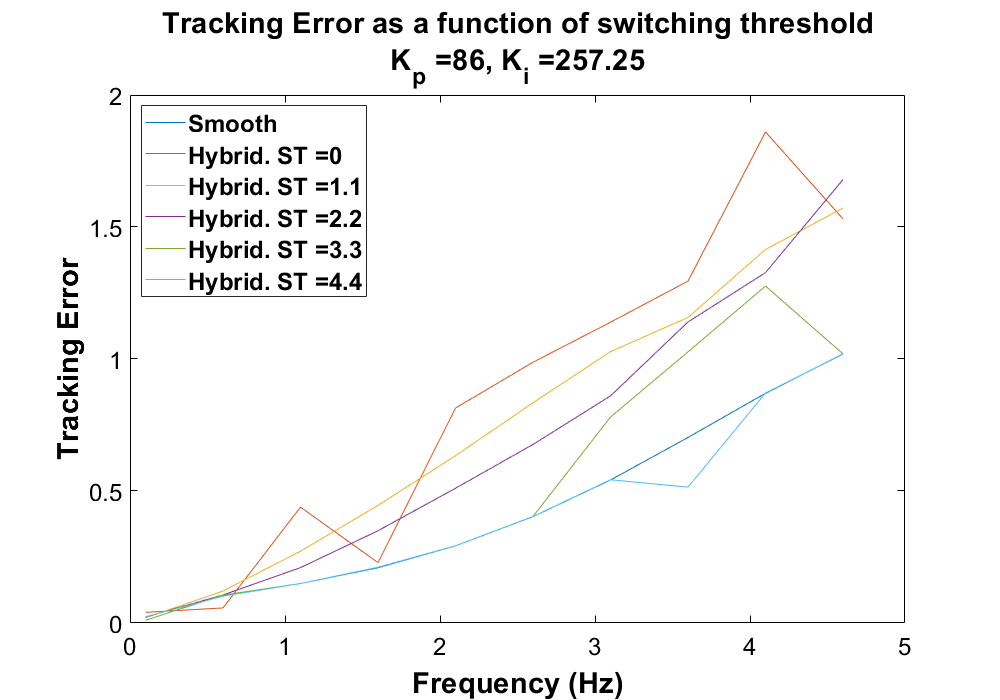

easyPlotter('increasingSwitchThresh','Kp',86,'Ki',257.3,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5,'normal')

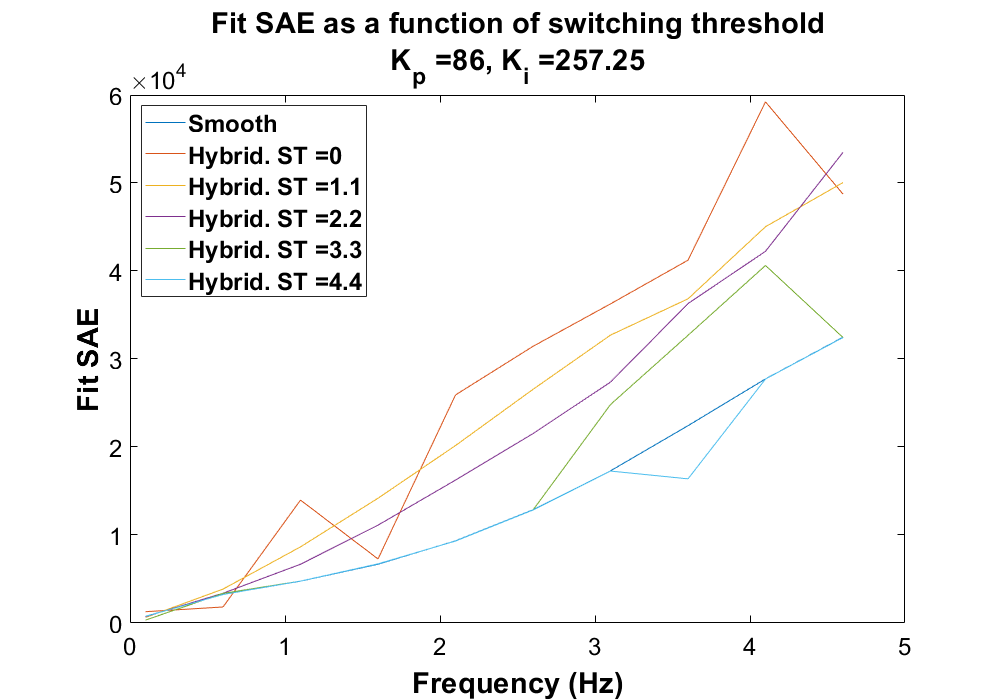


easyPlotter('increasingSwitchThresh','Kp',86,'Ki',257.3,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5,'FitSAE')

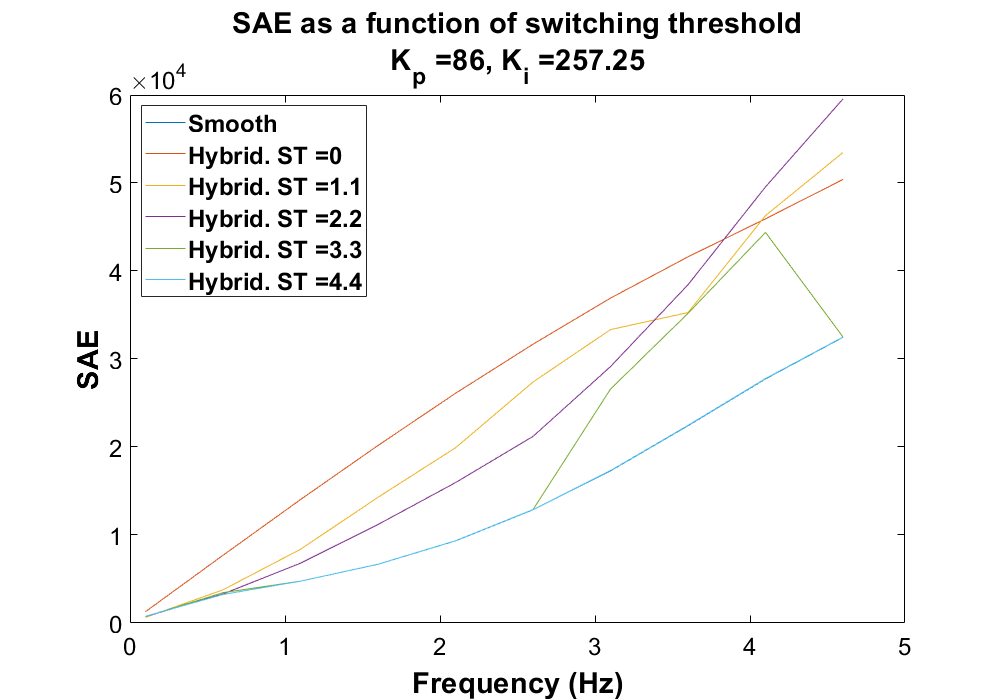


easyPlotter('increasingSwitchThresh','Kp',86,'Ki',257.3,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5,'SAE')

# Plot some other stuff

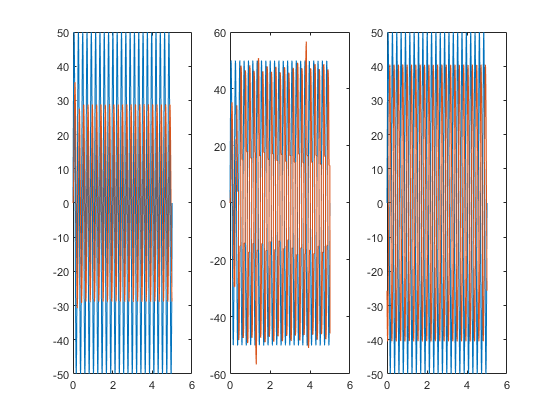

kpIndex = 14

kiIndex = 13

stIndex = 31

fIndex = 10

[kpIndex,kiIndex,stIndex,fIndex] = responsePlot(Kp,Ki,switchThresh,...
    sinfreqsDecimate,86,257.3,3,4.6,pureSinTime,sweepData)

sweepData(kpIndex,kiIndex,fIndex)

ans = struct with fields:
            Kp: 53
            Ki: 390.2800
     inputFreq: 4.6000
     smoothOut: [1001×1 double]
         sGain: 0.5751
        sPhase: -1.4819
        sError: 1.1085
    hybridInfo: [1×51 struct]


sweepData(kpIndex,kiIndex,fIndex).hybridInfo(stIndex)

ans = struct with fields:
    switchThresh: 3
       hybridOut: [1×1001 double]
            hFit: [1×1001 double]
           hGain: 0.8102
          hPhase: 3.8294
          hError: 1.7054
         rsquare: 0.7442


# Statistics

r2thresh = 0.4;
[bads,goods,bests,totalij,totalijk,totalijkl] = badFitList(sweepData,r2thresh);
percentBadFit = 100*size(bads,1)/totalijkl; 
percentBetter = 100*size(goods,1)/totalijkl;

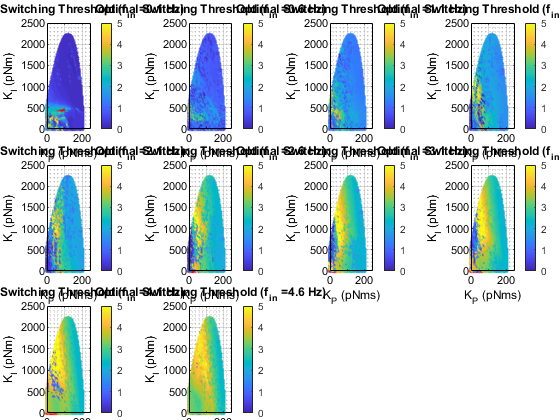

[~] = SlicePerformance(bests,sinfreqsDecimate,commonPath,'bool','');

% [~] = SlicePerformance(bests,sinfreqsDecimate,commonPath,'contour','nofit');
% [bestfreqs] = SlicePerformance(bests,sinfreqsDecimate,commonPath,'contour','');

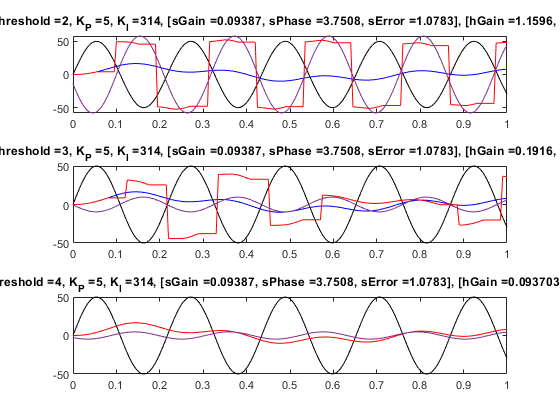

kpIndex = 2

kiIndex = 20

fIndex = 10

[kpIndex,kiIndex,fIndex] = responsePlotSwitch(Kp,Ki,switchThresh,...
    sinfreqsDecimate,5,314,4.6,pureSinTime,sweepData)

# Tracking Error Function

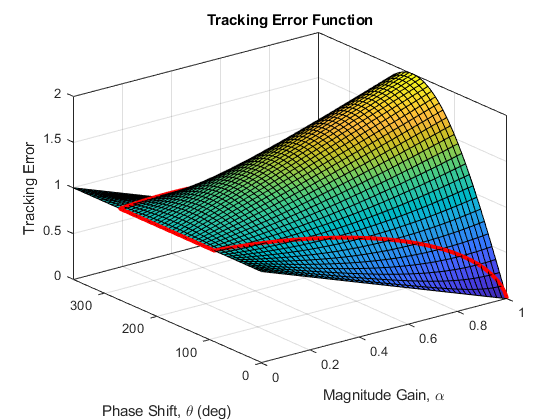

figure
%tiledlayout(1,4, 'Padding', 'none', 'TileSpacing', 'compact');
teAlpha = 0:0.001:1;
teTheta = 0:0.005:2*pi;
H = zeros(length(teAlpha)*length(teTheta),3);
HminTrip = zeros(length(teTheta),3);
iter = 1;
for i = 1:length(teTheta)
    Hmin = inf;
    for j = 1:length(teAlpha)
        H(iter,:) = [teAlpha(j) rad2deg(teTheta(i)) abs(teAlpha(j)*cos(teTheta(i))-1 + teAlpha(j)*sin(teTheta(i))*1i)];
        if H(iter,3) < Hmin
            Hmin = H(iter,3);
            HminTrip(i,:) = H(iter,:);
        end
        iter = iter + 1;
    end
end


sf = fit([H(:,1),H(:,2)],H(:,3),'cubicinterp');
plot(sf)
hold on
plot3(HminTrip(:,1),HminTrip(:,2),HminTrip(:,3),'r','LineWidth',3)
title('Tracking Error Function')
xlabel('Magnitude Gain, \alpha')
ylabel('Phase Shift, \theta (deg)')
zlabel('Tracking Error')

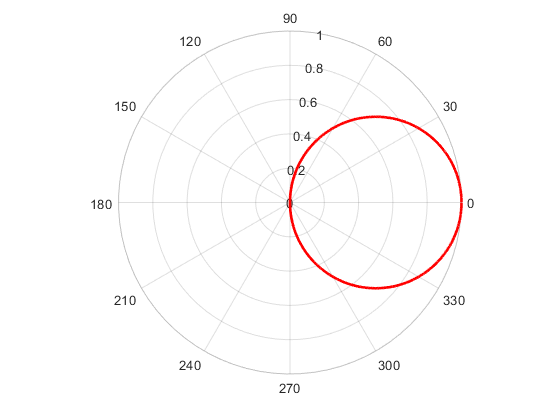


figure
polarplot(deg2rad(HminTrip(:,2)),HminTrip(:,1),'r','LineWidth',2)

# Sin waves and phase shift

t = 0:0.01:10;
sin1 = sin(t)

sin1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


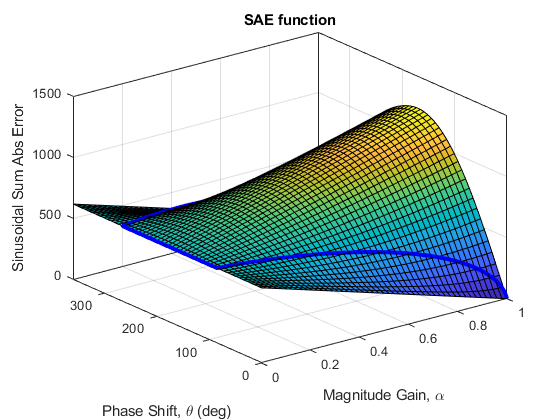


figure
sseAlpha = 0:0.001:1;
sseTheta = 0:0.005:2*pi;
S = zeros(length(sseAlpha)*length(sseTheta),3);
SminTrip = zeros(length(sseTheta),3);
iter = 1;
for i = 1:length(sseTheta)
    Smin = inf;
    for j = 1:length(sseAlpha)
        sin2 = sseAlpha(j)*sin(t-sseTheta(i));
        S(iter,:) = [sseAlpha(j) rad2deg(sseTheta(i)) sum(abs(sin1-sin2))];
        if S(iter,3) < Smin
            Smin = S(iter,3);
            SminTrip(i,:) = S(iter,:);
        end
        iter = iter + 1;
    end
end

sf = fit([S(:,1),S(:,2)],S(:,3),'cubicinterp');
plot(sf)
hold on
plot3(SminTrip(:,1),SminTrip(:,2),SminTrip(:,3),'b','LineWidth',3)
title('SAE function')
xlabel('Magnitude Gain, \alpha')
ylabel('Phase Shift, \theta (deg)')
zlabel('Sinusoidal Sum Abs Error')

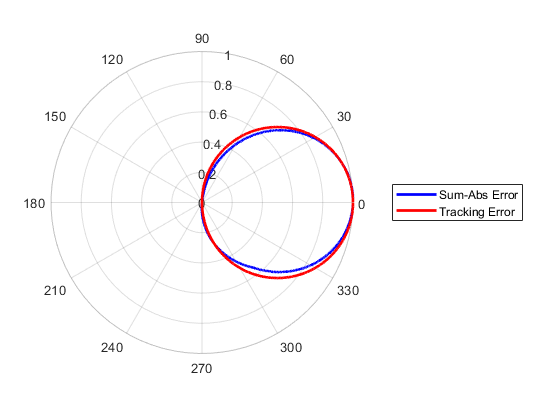


figure
polarplot(deg2rad(SminTrip(:,2)),SminTrip(:,1),'b','LineWidth',2)
hold on
polarplot(deg2rad(HminTrip(:,2)),HminTrip(:,1),'r','LineWidth',2)
legend('Sum-Abs Error','Tracking Error')

# Animate Hybrid Response

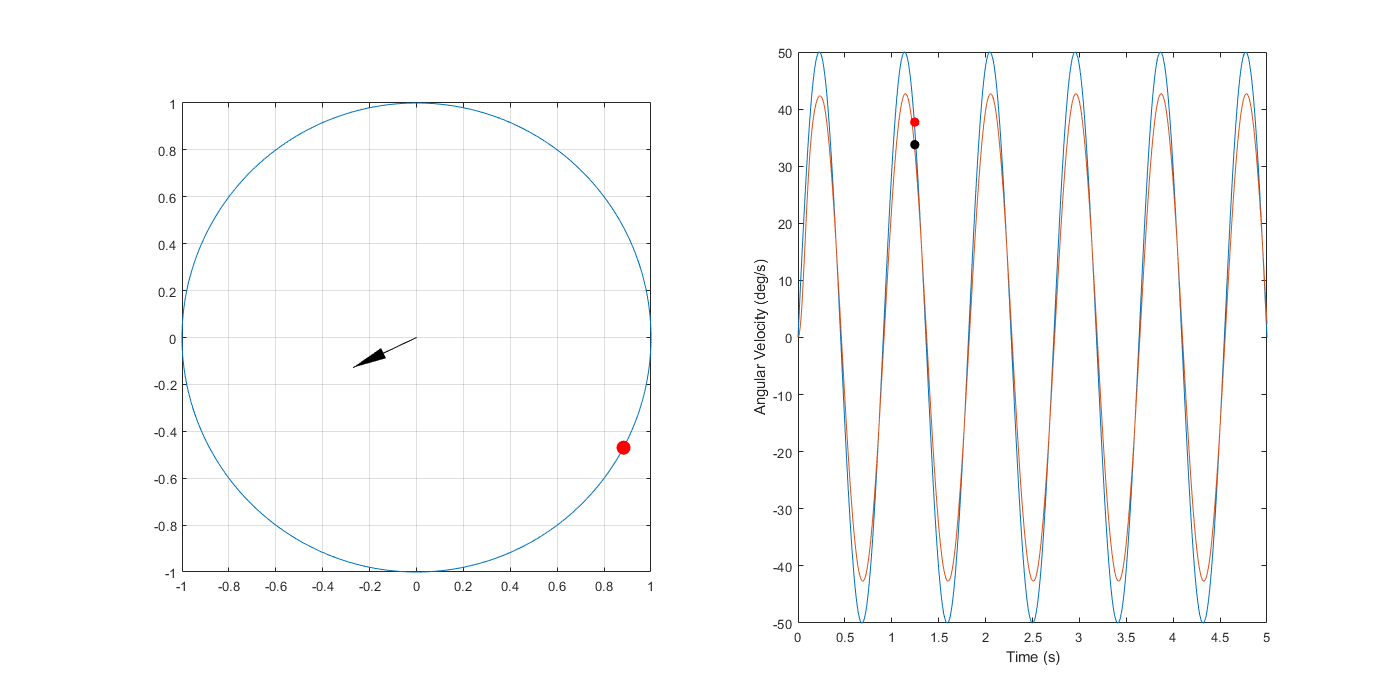

basepath = strcat(commonPath,'\HybridAnimation');
savePath = genFileName(basepath,'HybridAnimation');
savePath = strrep(savePath,'.mat','.avi');
hybridOut = sweepData(kpIndex,kiIndex,fIndex).hybridInfo(stIndex).hybridOut;
smoothOut = sweepData(kpIndex,kiIndex,fIndex).smoothOut;
sinin = 50*sin(2*pi*sinfreqsDecimate(fIndex).*pureSinTime);
AnimationPlotter(sinin,smoothOut,pureSinTime,savePath)

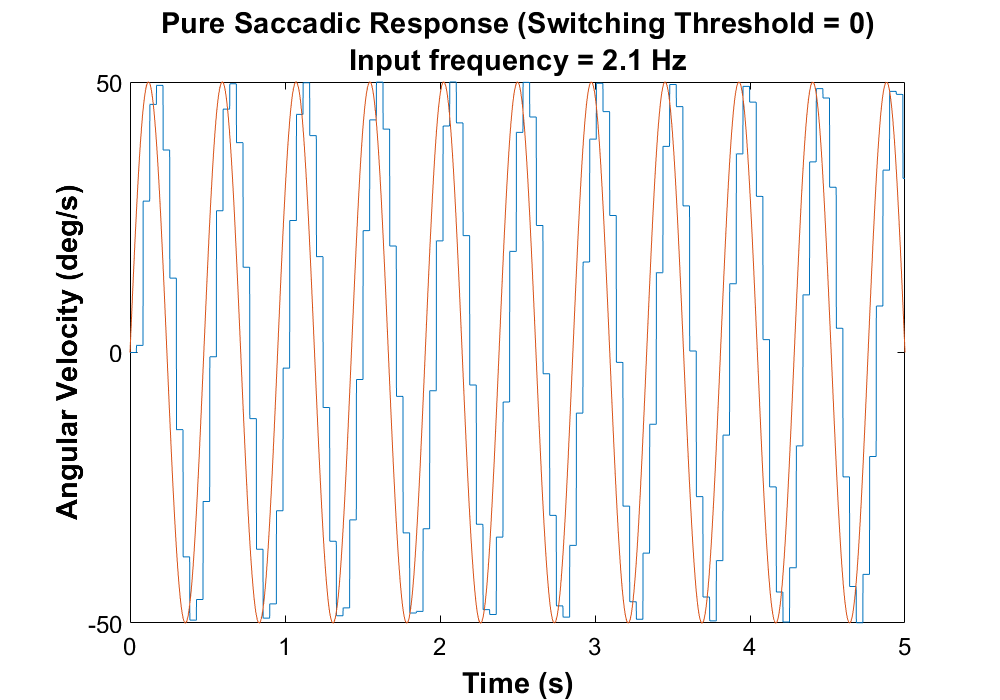




figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,1,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Pure Saccadic Response (Switching Threshold = 0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

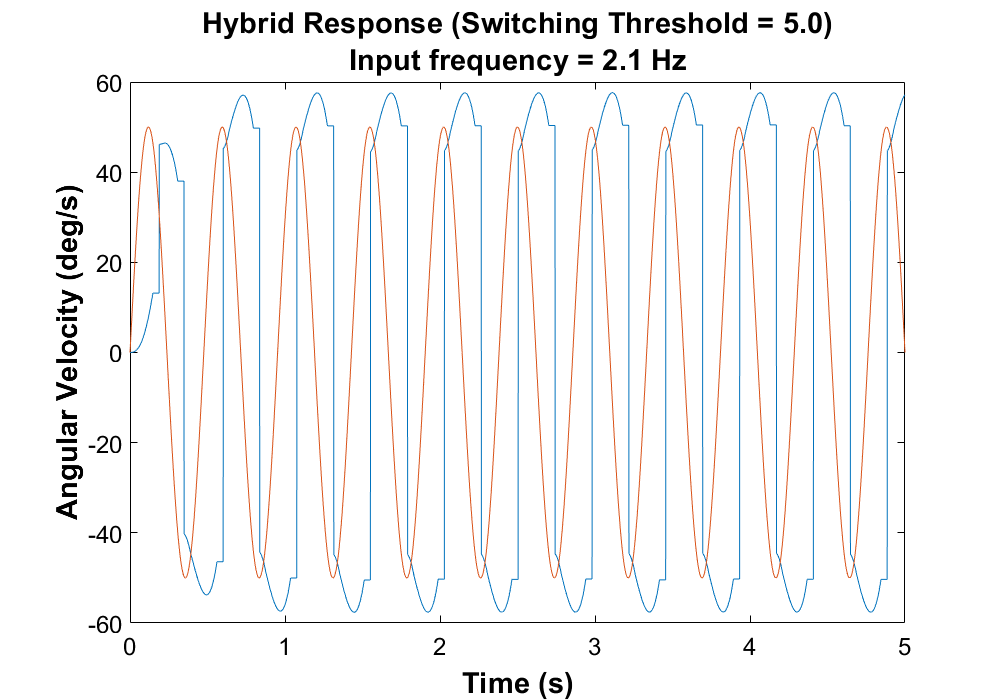


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,11,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response (Switching Threshold = 5.0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

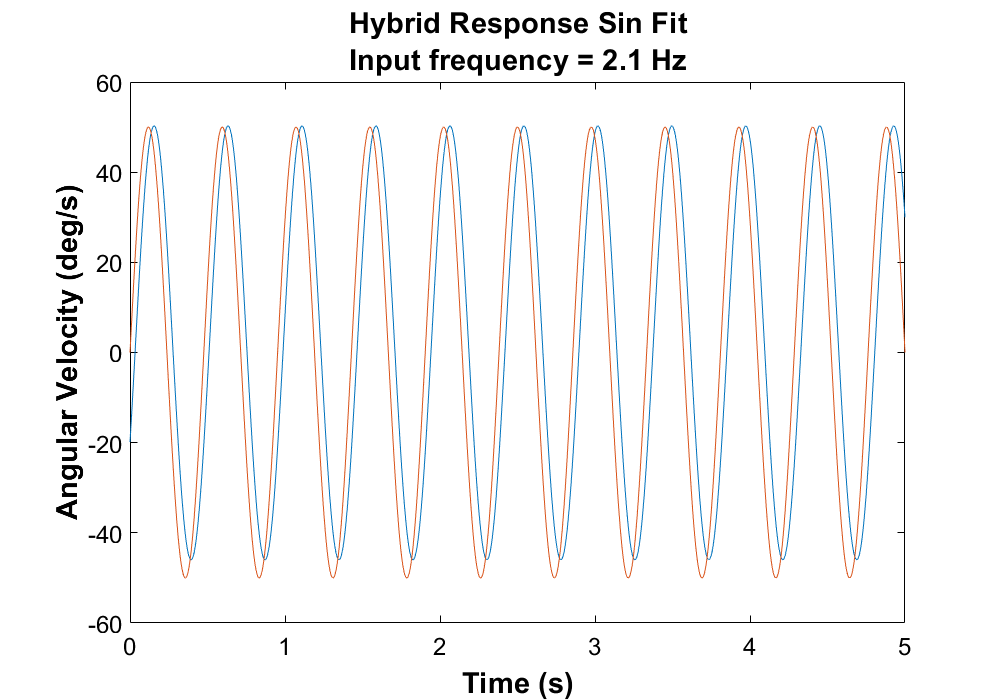


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(5,5,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hFit,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response Sin Fit','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

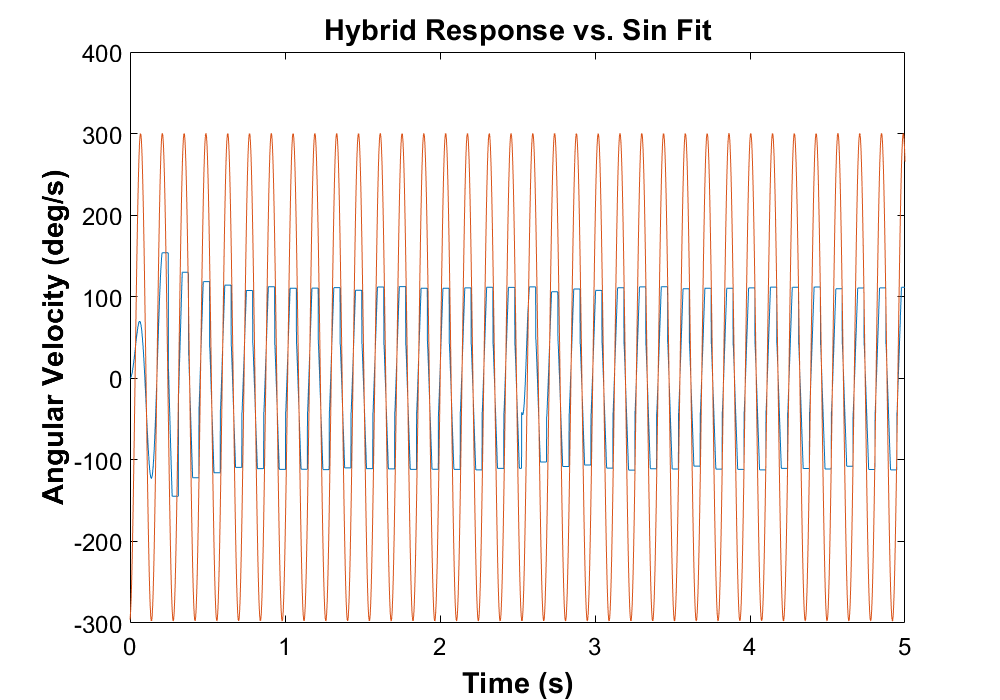


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(9,2,10,15);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,chosenPoint.hFit)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response vs. Sin Fit'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

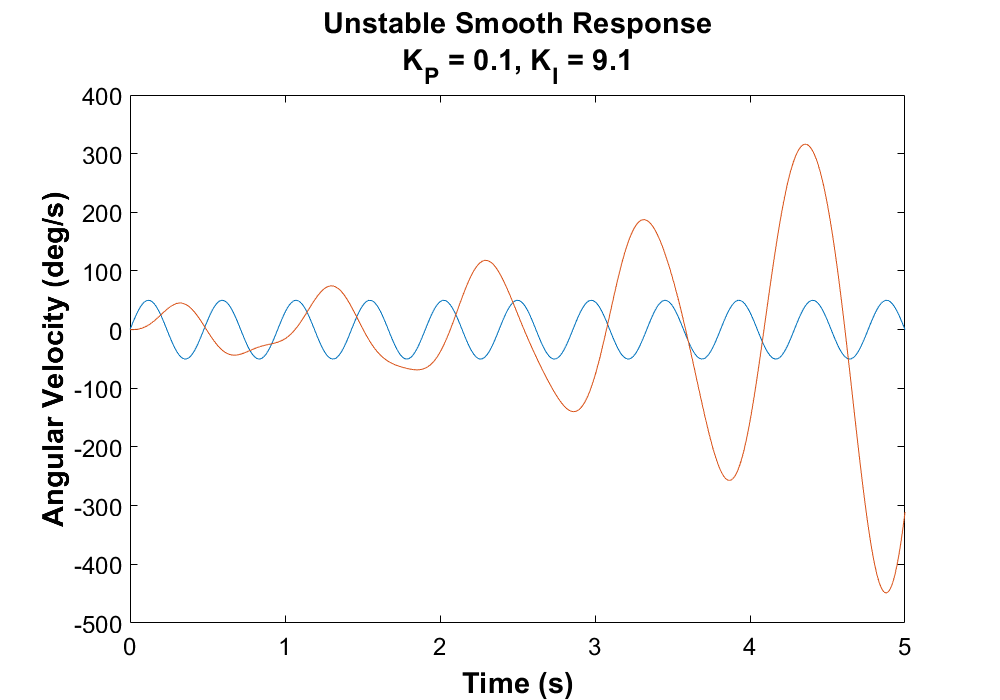



chosenPoint = sweepData(1,10,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
C_tf = tf([0.1 9.1],[1 0]);

%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
den = (1 + num*d_tf);
cl_tf = num/den;

unstable = lsim(cl_tf,sinin,pureSinTime);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(pureSinTime,sinin,pureSinTime,unstable)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Unstable Smooth Response','K_P = 0.1, K_I = 9.1'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')